# Actividad Práctica N°3: Diseño de controladores considerado la dinámica del error y la magnitud de la acción de control en sistemas no lineales multivariables

## Caso de estudio 1. Sistema de tres variables de estado.

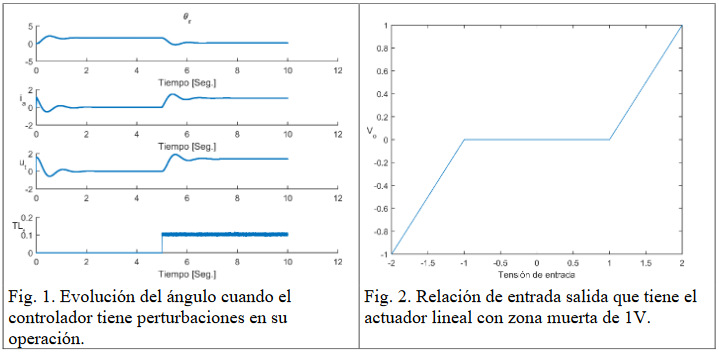

**Ítem [1] **Implementar un sistema en variables de estado que controle el ángulo del motor para consignas de $\frac{\pi }{2}$ y $-\frac{\pi }{2}$ cambiando cada 5 segundos y que el $T_L =0\ldotp 115\;\textrm{Nm}$ aparece sólo para $\frac{\pi }{2}$, para $-\frac{\pi }{2}$ es nulo. Hallar el valor de integración Euler adecuado.

Objetivo: acelerar la dinámica del controlador que muestra la figura 1 aunque ésta se muestre en otra escala de tiempo, verificando el resultado con las curvas del archivo xlsx adjunto.

- Evitando que la tensión supere los $24\;V$ en valor absoluto, especificar el tiempo de muestreo necesario para que el controlador cumpla el objetivo.

- Asumiento que no puede medirse directamente, proponer un controlador que logre el objetivo.

- Determinar el efecto de la no linealidad en la acción de control, descripta en la figura 2, y verificar cuál es el máximo valor admisible de esa no linealidad.

clear all;
close all;
clc;

Se comienza definiendo los parámetros del sistema:

Laa = 0.56e-3;
J = 0.0019;
Ra = 1.35;
Bm = 0.000792;
Ki = 0.1;
Km = 0.1;

Se plantea el sistema en variables de estado:

A = [-Ra/Laa -Km/Laa 0; Ki/J -Bm/J 0; 0 1 0]

A = 	1.0e+03 *

   -2.4107   -0.1786         0
    0.0526   -0.0004         0
         0    0.0010         0


B = [1/Laa 0; 0 -1/J; 0 0]

B = 	1.0e+03 *

    1.7857         0
         0   -0.5263
         0         0


C = [0 0 1]

C =      0     0     1


D = [0 0]

D =      0     0


sys = ss(A,B,C,D)

sys =
 
  A = 
            x1       x2       x3
   x1    -2411   -178.6        0
   x2    52.63  -0.4168        0
   x3        0        1        0
 
  B = 
           u1      u2
   x1    1786       0
   x2       0  -526.3
   x3       0       0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



Se ven los polos del sistema:

pole(sys)

ans = 	1.0e+03 *

         0
   -0.0043
   -2.4068


Para calcular el tiempo de integración:

tr = log(0.95)/-2.4068e3

tr = 2.1312e-05

h = 1e-6;
Ts = 1e-5;
T = 10;
Kmax = T/h;

Con esto, se plantea el sistema discretizado con un retentor de orden cero.

dSys = c2d(sys,Ts,'zoh')

dSys =
 
  A = 
              x1         x2         x3
   x1     0.9762  -0.001764          0
   x2    0.00052          1          0
   x3  2.611e-09      1e-05          1
 
  B = 
               u1          u2
   x1     0.01764   4.662e-06
   x2   4.662e-06   -0.005263
   x3   1.557e-11  -2.632e-08
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 1e-05 seconds
Discrete-time state-space model.



Se redefinen las matrices, siendo estas ahora las del sistema discretizado: 

A = dSys.A

A =     0.9762   -0.0018         0
    0.0005    1.0000         0
    0.0000    0.0000    1.0000


B = dSys.B

B =     0.0176    0.0000
    0.0000   -0.0053
    0.0000   -0.0000


Para plantear un controlador LQR en tiempo discreto, se plantea la siguiente matriz Q:

Q = diag([1 0.1 100])

Q =     1.0000         0         0
         0    0.1000         0
         0         0  100.0000


R = 1;
K = dlqr(A,B(:,1),Q,R)

K =     0.3383    0.7534    9.9694


Se obtiene G para la simulacion:

G = inv(C*inv(eye(length(A))-A+B(:,1)*K)*B(:,1)) 

G = 9.9694

Para la simulación propiamente dicha:

ia(1) = 0;
omega(1) = 0;
omegaP(1) = 0;
theta(1) = 0;
reference(1) = 0;

Las siguientes son variables para un sistema lineal (subíndice l):

ial(1) = 0;
omegal(1) = 0;
omegaPl(1) = 0;
thetal(1) = 0;

Se declaran vectores y variables auxiliares para simular:

t = linspace(0,T,Kmax+1);
tl = linspace(0,T,Kmax*(Ts/h)+1);
thetaRef = pi/2;
torqueRef = 0;
%zonaMuerta = deadzone('ZeroInterval',[-1,1])
deadZone = 1;
saturation = 24;
xop = [0;0;0];
x = [ial(1);omegal(1);thetal(1)];
stateVector = [ia(1);omega(1);theta(1)];
xol = [0;0;0];
ii = 0;
jj = 1;
Tl = torqueRef;
reference(1) = thetaRef;
u(1) = 0;
uk(1) = 0;
yOut(1) = 0;
yOutl(1) = 0;
ul(2,:) = 0;

Bucle de simulacion:

for i = 1:Kmax
    ii = ii+h;
    if (ii >= 5)
        thetaRef = -pi/2;
        Tl = 0;
        ii = 0;
    end
    reference(i) = thetaRef;
    ul(:,i) = [-K*x+G*reference(i);Tl];
    uk(i) = -K*stateVector+G*reference(i);
    % Esto es para las zonas muertas de la accion de control
    if (ul(1,i) < -deadZone)
        ul(1,i) = ul(1,i)+deadZone;
    elseif (ul(1,i) >= deadZone)
        ul(1,i) = ul(1,i)-deadZone;
    else
        ul(1,i) = 0;
    end
    if (uk(i) <- deadZone)
        uk(i) = uk(i)+deadZone;
    elseif (uk(i)>= deadZone)
        uk(i) = uk(i)-deadZone;
    else
        uk(i) = 0;
    end
    % Esto es para la saturacion de la accion de control en 24V
    ul(1,i) = min(saturation,max(-saturation,ul(1,i)));
    uk(i) = min(saturation,max(-saturation,uk(i)));
    yOut(i) = C*stateVector;
    for k = 1:Ts/h
        u(jj) = uk(i);
        omegaPP = (-omegaP(jj)*(Ra*J+Laa*Bm)-omega(jj)*(Ra*Bm+Ki*Km)+u(jj)*Ki)/(J*Laa);
        iaP = (-Ra*ia(jj)-Km*omega(jj)+u(jj))/Laa;
        omegaP(jj+1) = omegaP(jj)+omegaPP*h-((1/J)*Tl);
        ia(jj+1) = ia(jj)+iaP*h;
        omega(jj+1) = omega(jj)+omegaP(jj)*h;
        theta(jj+1) = theta(jj)+omega(jj)*h;
        stateVector = [ia(jj);omega(jj);theta(jj)];
        jj = jj+1;
    end
    x = A*(x-xop)+B*ul(:,i);
    ial(i+1) = x(1);
    omegal(i+1) = x(2);
    thetal(i+1) = x(3);
end
ul(:,i+1) = ul(:,i);
ul = ul(1,:);
u(jj) = u(jj-1);
reference(i+1) = reference(i);

Se visualizan los resultados:

plot(tl,theta,'LineWidth',2)
title('Angulo de salida \theta')
xlabel('Tiempo [seg]')
ylabel('Angulo [rad]')
grid
plot(tl,u,'LineWidth',2)

Error using getByteStreamFromArray
Error during serialization

Error in matlab.internal.editor.figure.SerializedFigureState/serialize

Error in matlab.internal.editor.FigureProxy/createWebFigureSnapshot

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager.saveSnapshot

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager.figureBeingCleared

Error in matlab.graphics.internal.clearNotify (

title('Accion de control u')
xlabel('Tiempo [seg]')
ylabel('Tension [V]')
grid
plot(tl,ia,'LineWidth',2)
title('Corriente de armadura i_a')
xlabel('Tiempo [seg]')
ylabel('Corriente [A]')
grid
plot(theta,omega,'LineWidth',2)
title('Plano de fase')
xlabel('\theta [rad]')
ylabel('\omega [rad/seg]')
grid